modulePath = 'C:/Users/Asus/Studia/Projekt IPS/dane - semestr 5/MATLAB_project/python_modules';
insert(py.sys.path, int32(0), modulePath);
load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

function pred_vector = model_chronos_expanding(y_train, y_test, step_length)
    modul = py.importlib.import_module('chronos_module_window');
    
    py.importlib.reload(modul);

    y_train_list = py.list(y_train(:)'); 
    y_test_list  = py.list(y_test(:)');
    
    result_list = modul.run_forecast_expanding(y_train_list, y_test_list, int32(step_length));
    
    pred_vector = result_list.double;
end

function results_py = model_hybrid(y_train, y_test, step_length,  ma_window, season_period)
    py_model = py.importlib.import_module("model_hybrid");
    results_py = py_model.model_hybrid(...
        y_train, ... 
        y_test, ...
        step_length, ...
        pyargs('ma_window', ma_window, 'season_period', season_period, 'verbose', true) ...
    ).double';
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

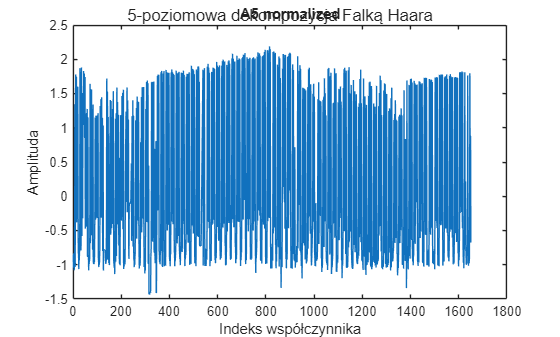

% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[D2_norm, center_D2, scale_D2] = normalize(D2);
[A5_norm, center_A5, scale_A5] = normalize(A5);

% 2. RYSOWANIE WYKRESÓW
plot(A5_norm);
title('A5 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');
sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
D2_test_norm = (D2_test - center_D2) ./ scale_D2;
A5_test_norm = (A5_test - center_A5) ./ scale_A5;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

step_length = 16;
step_length_A5 = ceil(step_length / 32);
step_length_D2 = ceil(step_length / 4);

dlugosc_testu_A5 = ceil(dlugosc_testu_oryginalna / 32);
dlugosc_testu_D2 = ceil(dlugosc_testu_oryginalna / 4);

% Przewidywania A5 - model CHRONOS
A5_pred_norm = model_chronos_expanding(A5_norm, A5_test_norm(1:dlugosc_testu_A5), step_length_A5)

CUDA dostepne: True
Wersja: 2.9.1+cu126
Ładowanie modelu Chronos-2 (Singleton)...
[Python Chronos] Start Expanding Window. Kroki: 90, Step: 1
[Python Chronos] Krok 1/90
[Python Chronos] Krok 2/90
[Python Chronos] Krok 3/90
[Python Chronos] Krok 4/90
[Python Chronos] Krok 5/90
[Python Chronos] Krok 6/90
[Python Chronos] Krok 7/90
[Python Chronos] Krok 8/90
[Python Chronos] Krok 9/90
[Python Chronos] Krok 10/90
[Python Chronos] Krok 11/90
[Python Chronos] Krok 12/90
[Python Chronos] Krok 13/90
[Python Chronos] Krok 14/90
[Python Chronos] Krok 15/90
[Python Chronos] Krok 16/90
[Python Chronos] Krok 17/90
[Python Chronos] Krok 18/90
[Python Chronos] Krok 19/90
[Python Chronos] Krok 20/90
[Python Chronos] Krok 21/90
[Python Chronos] Krok 22/90
[Python Chronos] Krok 23/90
[Python Chronos] Krok 24/90
[Python Chronos] Krok 25/90
[Python Chronos] Krok 26/90
[Python Chronos] Krok 27/90
[Python Chronos] Krok 28/90
[Python Chronos] Krok 29/90
[Python Chronos] Krok 30/90
[Python Chronos] Krok 31/90

A5_pred_norm =    -0.4648    1.5547   -0.7891   -0.8438    1.6016    0.2402   -0.3516    1.7188    0.0913   -0.9023   -0.9062   -0.8633   -0.9375   -0.8711   -0.8555   -0.5234    1.5078   -0.6758   -0.5078    1.4844   -0.3047   -0.3301    1.5938   -0.0388   -0.4023    1.5859   -0.2363   -0.4707    1.7969    0.0903   -0.9102   -0.8945   -0.9375   -0.9062   -0.8828   -0.9141   -0.4434    1.7344   -0.1562   -0.3574    1.7812   -0.1533   -0.2139    1.7344    0.1357   -0.4258    1.8516    0.4902   -0.4023    1.8203


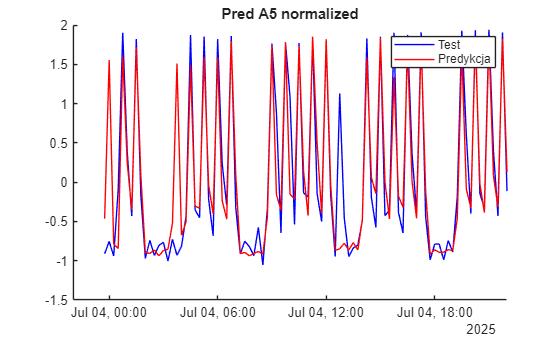


% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_test_norm(1:dlugosc_testu_A5), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A5 normalized');
legend;

% Przewidywania D2 - model HW-ELM
D2_pred_norm = model_hybrid(D2_norm, D2_test_norm(1:dlugosc_testu_D2), step_length_D2, 8 ,24)

Step: 1 / 180
Step: 2 / 180
Step: 3 / 180
Step: 4 / 180
Step: 5 / 180
Step: 6 / 180
Step: 7 / 180
Step: 8 / 180
Step: 9 / 180
Step: 10 / 180
Step: 11 / 180
Step: 12 / 180
Step: 13 / 180
Step: 14 / 180
Step: 15 / 180
Step: 16 / 180
Step: 17 / 180
Step: 18 / 180
Step: 19 / 180
Step: 20 / 180
Step: 21 / 180
Step: 22 / 180
Step: 23 / 180
Step: 24 / 180
Step: 25 / 180
Step: 26 / 180
Step: 27 / 180
Step: 28 / 180
Step: 29 / 180
Step: 30 / 180
Step: 31 / 180
Step: 32 / 180
Step: 33 / 180
Step: 34 / 180
Step: 35 / 180
Step: 36 / 180
Step: 37 / 180
Step: 38 / 180
Step: 39 / 180
Step: 40 / 180
Step: 41 / 180
Step: 42 / 180
Step: 43 / 180
Step: 44 / 180
Step: 45 / 180
Step: 46 / 180
Step: 47 / 180
Step: 48 / 180
Step: 49 / 180
Step: 50 / 180
Step: 51 / 180
Step: 52 / 180
Step: 53 / 180
Step: 54 / 180
Step: 55 / 180
Step: 56 / 180
Step: 57 / 180
Step: 58 / 180
Step: 59 / 180
Step: 60 / 180
Step: 61 / 180
Step: 62 / 180
Step: 63 / 180
Step: 64 / 180
Step: 65 / 180
Step: 66 / 180
Step: 67 / 180
Step

D2_pred_norm =    -2.0972    4.2640  -14.9129   20.3344    0.0234   -2.0738    4.0603  -14.7153    3.4430   -7.7612   20.2992   -3.8167    4.5134   -8.4741   25.6210    4.8635    1.2409   -2.3866    8.9160  -18.4547   -6.5924   16.1429  -21.3995    8.0098    3.5605  -11.7619   20.2227  -14.3174    2.4348   -5.2542   16.2666  -14.6116    3.1171   -6.7419   19.4724   -9.0827   -0.5266    2.0520   -5.5023   16.0687   -1.7612    6.3082  -15.8998   18.3006    0.4426   -0.3213    1.9837   -5.2612    1.4949   -3.6676


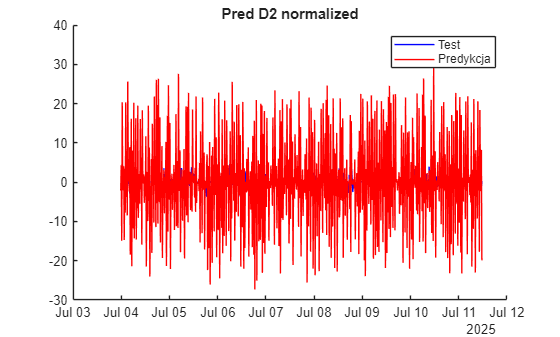



% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_D2), D2_test_norm(1:dlugosc_testu_D2), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_D2), D2_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred D2 normalized');
legend;

% DENORMALIZACJA
% Odwracamy proces: x = y * scale + center
A5_pred = (A5_pred_norm .* scale_A5) + center_A5;
D2_pred = (D2_pred_norm .* scale_D2) + center_D2;

% Obliczamy długości wektorów dla brakujących poziomów (dla zadanego horyzontu)
len_A5 = length(A5_pred);
len_D5 = len_A5;      % Z własności Haara
len_D4 = len_A5 * 2;
len_D3 = len_A5 * 4;
len_D2 = len_A5 * 8;
len_D1 = len_A5 * 16;

% Budowa wektora c_pred
c_pred = [
    A5_pred';             % Predykcja CHRONOS
    zeros(len_D5, 1);     % D5 - zerujemy
    zeros(len_D4, 1);     % D4 - zerujemy
    zeros(len_D3, 1);     % D3 - zerujemy
    D2_pred';             % Predykcja CHRONOS
    zeros(len_D1, 1);     % D1 - zerujemy
];

total_len = length(c_pred);
l_pred = [
    length(A5_pred);
    length(A5_pred);      % D5
    length(A5_pred)*2;    % D4
    length(A5_pred)*4;    % D3
    length(A5_pred)*8;    % D2
    length(A5_pred)*16;   % D1
    length(A5_pred)*32    % Całkowita długość sygnału
];

final_prediction = waverec(c_pred, l_pred, 'haar');      % podejście: A5 i D2 CHRONOS
y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction')

mae_score = 0.6876

mape_score = mape(y_test, final_prediction')

mape_score = 224.8026

rmse_score = rmse(y_test, final_prediction')

rmse_score = 0.8901

r2_classic = R2_classic(y_test, final_prediction')

r2_classic = -5.6103

r2_alt = R2_alt(y_test, final_prediction')

r2_alt = 6.5677

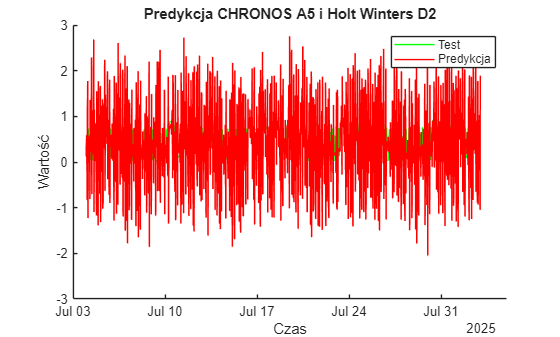


figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ab_diff_test_norm(1:dlugosc_testu_oryginalna), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja CHRONOS A5 i Holt Winters D2")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   final_prediction(1:dlugosc_testu_oryginalna), ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, "pred_ab_A5_D2_CHRONOS_HYBRYDA_month_"+ num2str(step_length)+".xlsx");